

s = tf('s');

% --- Multi-Objective Genetic Algorithm Setup ---
% The goal is to find the optimal parameters for our 3rd order filters
% that meet our performance and robustness goals.

% The optimization variables are the parameters that define W1 and W3:
% x = [M_s, wb_s, M_t, wb_t]
n_vars = 4;

% Bounds for the parameters to guide the search. This is crucial for
% ensuring the optimizer searches within a reasonable space.
lb = [1,  0.05, 1.05, 0.5];  % Lower bounds for [M_s, wb_s, M_t, wb_t]
ub = [100, 1.0,  10,  10.0]; % Upper bounds for [M_s, wb_s, M_t, wb_t]

% Set options for the genetic algorithm
options = optimoptions('gamultiobj', 'Display', 'iter', 'PopulationSize', 100);

fprintf('\n--- Running Multi-Objective Genetic Algorithm ---\n');


--- Running Multi-Objective Genetic Algorithm ---


% Run the optimizer. The objective function will return two values:
% [gamma, constraint_penalty]
[x_pareto, fval_pareto] = gamultiobj(@(x) multiObjectiveFunction(x, P_pitch), n_vars, [], [], [], [], lb, ub, [], options);


Multi-objective optimization:
4 Variables

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverintermediate
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationadaptfeasible

                              Average            Average
Generation   Func-count    Pareto distance    Pareto spread
    1           100                 1                 1
    2           200                 0          0.290895
    3           300         0.0734409          0.173383
    4           400         0.0388904          0.568107
    5           500         0.0354186          0.504794
    6           600                 0          0.650479
    7           700         0.0119296          0.250637
    8           800                 0                 1
    9           900                 0                 1
   10          1000        0.00997602          0.116252
   11          1100        0.00798666           0.11801
   12          1200         0.0173958          0.38



% --- Process and Display Results ---
disp('Multi-objective optimization finished.');

Multi-objective optimization finished.


disp(['Found ' num2str(size(x_pareto, 1)) ' Pareto-optimal solutions.']);

Found 35 Pareto-optimal solutions.



% Find the best solution: one where all constraints are met (penalty is zero).
feasible_solutions_idx = find(fval_pareto(:, 2) < 1e-6); 

if isempty(feasible_solutions_idx)
    disp('Warning: No solution perfectly satisfied all constraints.');
    disp('Selecting the solution with the smallest constraint violation.');
    % Fallback: find the solution with the lowest penalty
    [~, best_idx] = min(fval_pareto(:, 2));
else
    % From the set of feasible solutions, pick the one with the lowest gamma
    fprintf('Found %d solutions that satisfy all constraints.\n', numel(feasible_solutions_idx));
    disp('Selecting the feasible solution with the minimum gamma.');
    [~, min_gamma_idx_in_feasible] = min(fval_pareto(feasible_solutions_idx, 1));
    best_idx = feasible_solutions_idx(min_gamma_idx_in_feasible);
end

Selecting the solution with the smallest constraint violation.



x_optimal = x_pareto(best_idx, :);


fprintf('\n--- Best Compromise Solution ---\n');


--- Best Compromise Solution ---


fprintf('Optimal Parameters [M_s, wb_s, M_t, wb_t]:\n');

Optimal Parameters [M_s, wb_s, M_t, wb_t]:


disp(x_optimal);

   1.006630607699811   0.061237082181830   1.275340858833914   9.755768335909259




% Reconstruct the optimal weighting functions for the selected solution
M_s_opt  = x_optimal(1);
wb_s_opt = x_optimal(2);
M_t_opt  = x_optimal(3);
wb_t_opt = x_optimal(4);
W1_optimal = M_s_opt * (1 / (s/wb_s_opt + 1))^3;
W3_optimal = M_t_opt * ( (s / wb_t_opt) / (s/wb_t_opt + 1) )^3;

disp('Optimal W1:');

Optimal W1:


disp(W1_optimal);

  tf with properties:

       Numerator: {[0 0 0 2.311604862601704e-04]}
     Denominator: {[1 0.183711246545489 0.011249940702432 2.296378477785220e-04]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



disp('Optimal W3:');

Optimal W3:


disp(W3_optimal);

  tf with properties:

       Numerator: {[1.184160881594449e+03 0 0 0]}
     Denominator: {[9.285054057447562e+02 2.717485091125582e+04 2.651115500530844e+05 8.621222884972342e+05]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]




% Calculate the controller and margins with the optimal weights
[K_optimal, ~, gamma_optimal] = mixsyn(P_pitch, W1_optimal, [], W3_optimal);
margins_optimal = allmargin(P_pitch * K_optimal);

fprintf('\n--- Performance of Best Compromise Solution ---\n');


--- Performance of Best Compromise Solution ---


fprintf('Final Gamma: %f\n', gamma_optimal);

Final Gamma: 0.002531


fprintf('Number of Gain Margins: %d\n', numel(margins_optimal.GainMargin));

Number of Gain Margins: 4


if ~isempty(margins_optimal.GainMargin)
    fprintf('Gain Margins (abs): %s\n', mat2str(margins_optimal.GainMargin, 3));
else
    fprintf('Gain Margin: Inf (or system is unstable)\n');
end

Gain Margins (abs): [0.604 5.68 19.9 7.74e+03]


if ~isempty(margins_optimal.PhaseMargin)
    fprintf('Phase Margin (deg): %f\n', min(margins_optimal.PhaseMargin));
else
    fprintf('Phase Margin: Inf (or system is unstable)\n');
end

Phase Margin (deg): -92.905955



disp('Optimal Controller K:');

Optimal Controller K:


disp(K_optimal);

  ss with properties:

                A: [10×10 double]
                B: [10×1 double]
                C: [-1.113044748288257e+02 -5.141602480494594e+02 -3.907441678993877e+03 -1.384702884506935e+04 -9.707969590547358e+03 -3.982221850879761e+03 -46.876366687461697 -8.924344752818735e+03 -1.201285523018408e+04 -6.047615551780402e+02]
                D: 0
                E: []
          Offsets: []
           Scaled: 0
        StateName: {10×1 cell}
        StatePath: {10×1 cell}
        StateUnit: {10×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: 0
      OutputDelay: 0
        InputName: {''}
        InputUnit: {''}
       InputGroup: [1×1 struct]
       OutputName: {''}
       OutputUnit: {''}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 0
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]



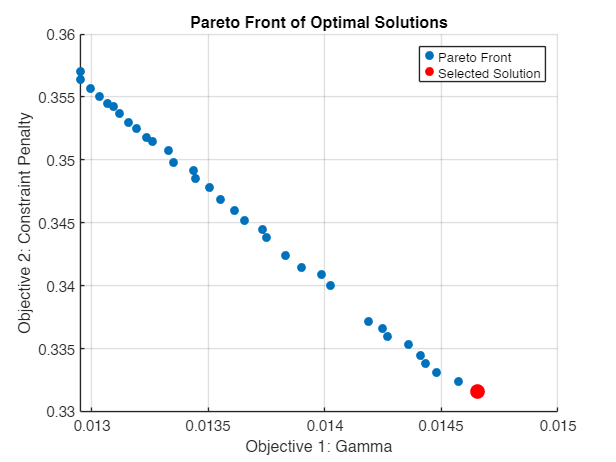


% --- Plot the Pareto Front ---
figure;
scatter(fval_pareto(:,1), fval_pareto(:,2), 'filled');
hold on;
% Highlight the selected "best" solution
scatter(fval_pareto(best_idx,1), fval_pareto(best_idx,2), 100, 'r', 'filled');
legend('Pareto Front', 'Selected Solution');
xlabel('Objective 1: Gamma');
ylabel('Objective 2: Constraint Penalty');
title('Pareto Front of Optimal Solutions');
grid on;



% --- Multi-Objective Function Definition ---
function objectives = multiObjectiveFunction(x, P_pitch)
    % This function calculates the two objective values for a given set of
    % filter parameters 'x'. The goal is to minimize both objectives.
    
    s = tf('s');
    
    % --- 1. Reconstruct Weighting Functions from Parameters ---
    M_s  = x(1);
    wb_s = x(2);
    M_t  = x(3);
    wb_t = x(4);
    
    W1 = M_s * (1 / (s/wb_s + 1))^2;
    W3 = M_t * ( (s / wb_t) / (s/wb_t + 1) )^2;

    % --- 2. Synthesize Controller ---
    try
        [K, ~, gamma] = mixsyn(P_pitch, W1, [], W3);
    catch
        % If mixsyn fails, return a very high cost for all objectives
        objectives = [1e12, 1e12]; 
        return;
    end
    
    % --- 3. Evaluate Stability Margins ---
    loop_transfer_function = P_pitch * K;
    margins = allmargin(loop_transfer_function);
    
    all_gms = margins.GainMargin;
    min_pm = min(margins.PhaseMargin);

    % --- 4. Check for Instability ---
    if isempty(min_pm) || isnan(min_pm) || min_pm < 0
        objectives = [1e12, 1e12];
        return;
    end
    
    % --- 5. Define the Two Objectives ---
    
    % Objective 1: Minimize gamma.
    obj1_gamma = gamma;
    
    % Objective 2: Minimize constraint violations.
    constraint_penalty = 0;
    
    % Gain Margin constraint: Check ALL gain margins
    target_gm = 1.0;
    for i = 1:numel(all_gms)
        if all_gms(i) < target_gm
            constraint_penalty = constraint_penalty + (target_gm - all_gms(i))^2;
        end
    end
    
    % Phase Margin constraint
    target_pm = 30.0;
    if min_pm < target_pm
        constraint_penalty = constraint_penalty + (target_pm - min_pm)^2;
    end
    
    % Gamma constraint
    target_gamma = 10.0;
    if gamma > target_gamma
        constraint_penalty = constraint_penalty + (gamma - target_gamma)^2;
    end

    % Return the vector of two objectives
    objectives = [obj1_gamma, constraint_penalty];
end
